#            Computational Electromagnetics 

##                           Sadiku-CHap3-Figure-3.31

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/23      

% ********************************************************************
% Application of the finite DIfference Method
% This program Involves the penetration of a lossless dielectric SPHERE
% by a plane wave. The program in the maximum absolute value of 
% Ey and Ez uring the final half-wave of time-stepping
% Assumption:
% +y-directed incident wave with components Ez and Hx
% I,J,K,NN, correspond to X,Y,Z, and Time.
% IMAX, JMAX, KMAX are the maximum values of x,y,z 
% NNMAX is the total number of timesteps.
% NHW represents one half-wave cycle.
% MED is the number of different uniform media sections.
% JS is the j-position of the plane wave front.

clear; clc; close all; format compact



    IMAX = 19; JMAX =39; KMAX =19;
    NMAX=2; NNMAX =500; NHW =40; MED =2; JS =3;
    DELTA = 3e-3; CL = 3.0e+08; F = 2.5e+09;

%  Define Scatterer Dimensions:
    OI = 19.5; OJ = 20.0; OK =19.0; RADIUS = 15.0;
    ER =[1.0;4.0] ;  % CONSTITUTIVE Parameters
    SIG  = [0.1; 0.0 ];


% Statement Function to compute position w.r.t center of Sphere:
    E0 = (1e-9)/(36*pi) ;
    U0 = (1e-7)*4*pi ;
    DT = DELTA/(2*CL);
    R = DT/E0;
    RA = (DT^2)/(U0* E0*(DELTA^2));
    RB = DT / (U0*DELTA);
    TPIFDT = 2.0*pi*F*DT ;
% ****************************************************************
% STEP # 1- Compute Media Parameters:
% ****************************************************************
CA  = 1 - R*SIG./ER;
    CB =    RA./ER;
    CBMRB = CB/RB;

%  (i) CALCULATE the Real/Actual Grid Points:


% Initialize the media arrays.index (M) determines which 
% medium each point is actually located in and is used to
% index into arrays which determine  the constitutive 
% parameters of the medium. There are seperate M determining 
% arrays for EX, EY, and EZ. These arrays correlate the
% integer values of I,J,K to the actual position within
% the lattice. COmputing these values ow and storing them in these 
% arrays as opposed to computing them each time they are 
% needed saves  a large amount of computation time!


x = 0:IMAX+1 ; y = 0:JMAX+1 ; z=0:KMAX+1;
[Mx,My,Mz] =ndgrid(x,y,z) ;
IXMED = ( sqrt( (Mx-OI+0.5).^2 + (My-OJ).^2 + (Mz-OK).^2 )<=RADIUS   )+1;
IYMED = ( sqrt( (Mx-OI).^2 + (My-OJ+0.5).^2 + (Mz-OK).^2 )<=RADIUS   )+1;
IZMED = ( sqrt( (Mx-OI).^2 + (My-OJ).^2 + (Mz-OK+0.5).^2 )<=RADIUS   )+1;


% ****************************************************************
% STEP # 2- Initialize Field Components:
% ****************************************************************
% Components for Output

    EY1 = zeros(1,JMAX+2);
    EZ1 = zeros(1,JMAX+2);

    EX = zeros(IMAX+2, JMAX+2, KMAX+2, NMAX+1);
    EY = zeros(IMAX+2, JMAX+2, KMAX+2, NMAX+1);
    EZ = zeros(IMAX+2, JMAX+2, KMAX+2, NMAX+1);
    HX = zeros(IMAX+2, JMAX+2, KMAX+2, NMAX+1);
    HY = zeros(IMAX+2, JMAX+2, KMAX+2, NMAX+1);
    HZ = zeros(IMAX+2, JMAX+2, KMAX+2, NMAX+1);

% ****************************************************************
% STEP # 3- USE FD/TD ALGORITHM TO GENERATE 
%           FIELD COMPONENTS     :
% ****************************************************************

% Since only field components at current time (t) and Previous 
% Two Time STEPS (t-1 AND t-2) ARE Required For Computation, 
% We save Memory Space By using the following INDICES:
%   NCUR is index in for time t
%   NPR1 is index in for t-1
%   NPR2 s index n for t-2


% NOTES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% *ind03c.m I incremented the time so it goes 1 2 3, instead of  0 1 2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



    NCUR =3;
    NPR1 = 2;
    NPR2 =1;
    for NN = 1:NNMAX % Time Loop
        if mod(NN,10)==0
            disp(['NN = ', num2str(NN)]) % Display Progress
        end
        % Next time step - move indices up a notch.
        NPR2=NPR1;
        NPR1= NCUR;
        NCUR = mod(NCUR,3)+1;
        for K=0:KMAX % Z loop
            for J=0:JMAX % Y Loop
                for I=0:IMAX % X Loop
                    % (ii)- APPLY SOFT Lattice Truncation Conditions
                    % ----x = delta/2
                    if (I==0)
                        if((K~=KMAX) && ( K~=0 ))
                            HY(0+1,J+1,K+1,NCUR)  = (  HY(1+1,J+1,K-1+1,NPR2) + HY(1+1,J+1,K+1,NPR2) + ...
                                HY(1+1,J+1,K+1+1,NPR2)        )/3;

                             HZ(0+1,J+1,K+1,NCUR)  = (  HZ(1+1,J+1,K-1+1,NPR2) + HZ(1+1,J+1,K+1,NPR2) + ...
                                HZ(1+1,J+1,K+1+1,NPR2)        )/3;

                        else 
                            if( K == KMAX)
                                HY(0+1,J+1,K+1,NCUR)  =  ( HY(0+1,J+1,K-1+1,NPR2)  + HY(0+1,J+1,K+1,NPR2)   ) /2;

                                HZ(0+1,J+1,K+1,NCUR)  =  ( HZ(0+1,J+1,K-1+1,NPR2)  + HZ(0+1,J+1,K+1,NPR2)   ) /2;
                            else 
                                HY(0+1,J+1,K+1,NCUR)  =  ( HY(0+1,J+1,K+1,NPR2)  + HY(0+1,J+1,K+1+1,NPR2)   ) /2;

                                HZ(0+1,J+1,K+1,NCUR)  =  ( HZ(0+1,J+1,K+1,NPR2)  + HZ(0+1,J+1,K+1+1,NPR2)   ) /2;

                            end
                        end
                    end
                    % ----y=0
                    if (J==0)
                        EX(I+1,0+1,K+1,NCUR) =EX(I+1,1+1,K+1,NPR2) ;
                        EZ(I+1,0+1,K+1,NCUR) =EZ(I+1,1+1,K+1,NPR2) ;
                    else
                        % ----y=JMAX
                        if(J==JMAX)
                            EX(I+1,JMAX+1,K+1,NCUR) =EX(I+1,JMAX-1+1,K+1,NPR2) ;
                            EZ(I+1,JMAX+1,K+1,NCUR) =EZ(I+1,JMAX-1+1,K+1,NPR2) ;
                        end
                    end
                    %----z=0
                    if (K==0)
                        if((I~=0)&&(I~=IMAX))
                            EX(I+1,J+1,0+1,NCUR) = ( EX(I-1+1,J+1,1+1,NPR2)+EX(I+1,J+1,1+1,NPR2) + EX(I+1+1,J+1,1+1,NPR2)  )/3 ;

                            EY(I+1,J+1,0+1,NCUR) = ( EY(I-1+1,J+1,1+1,NPR2)+EY(I+1,J+1,1+1,NPR2) + EY(I+1+1,J+1,1+1,NPR2)  )/3 ;
                        else
                            if(I==0 )
                                EX(0+1,J+1,0+1,NCUR) = ( EX(0+1,J+1,1+1,NPR2)+EX(1+1,J+1,1+1,NPR2))/2;

                                EY(0+1,J+1,0+1,NCUR) = ( EY(0+1,J+1,1+1,NPR2)+EY(1+1,J+1,1+1,NPR2))/2;

                            else
                                EX(I+1,J+1,0+1,NCUR) = ( EX(I-1+1,J+1,1+1,NPR2)+EX(I+1,J+1,1+1,NPR2))/2;

                                EY(I+1,J+1,0+1,NCUR) = ( EY(I-1+1,J+1,1+1,NPR2)+EY(I+1,J+1,1+1,NPR2))/2;
                            end
                        end
                    end

                    % (iii) APPLY FD/TD ALGORITHM

                    % -----a. HX generation: 
                    HX(I+1,J+1,K+1,NCUR) = HX(I+1,J+1,K+1,NPR1) + RB*( EY(I+1,J+1,K+1+1,NPR1) - EY(I+1,J+1,K+1,NPR1) +EZ(I+1,J+1,K+1,NPR1) - EZ(I+1,J+1+1,K+1,NPR1)  ) ;
                    % -----b. HY generation:
                    HY(I+1,J+1,K+1,NCUR) = HY(I+1,J+1,K+1,NPR1) + RB*( EZ(I+1+1,J+1,K+1,NPR1) - EZ(I+1,J+1,K+1,NPR1) +EX(I+1,J+1,K+1,NPR1) - EX(I+1,J+1,K+1+1,NPR1)  ) ;
                    % -----c. HZ generation:
                    HZ(I+1,J+1,K+1,NCUR) = HZ(I+1,J+1,K+1,NPR1) + RB*( EX(I+1,J+1+1,K+1,NPR1) - EX(I+1,J+1,K+1,NPR1) +EY(I+1,J+1,K+1,NPR1) - EY(I+1+1,J+1,K+1,NPR1)  ) ;
                     % -----k=Kmax: ! Symmetry
                    if(K==KMAX)
                        HX(I+1,J+1,KMAX+1,NCUR) = HX(I+1,J+1,KMAX-1+1,NCUR);
                        HY(I+1,J+1,KMAX+1,NCUR) = HY(I+1,J+1,KMAX-1+1,NCUR);
                    end
                     % -----d. EX generation:
                     if( (J~=0)&&(J~=JMAX)&&(K~=0))
                         M = IXMED(I+1,J+1,K+1);
                         EX(I+1,J+1,K+1,NCUR) = CA(M)*EX(I+1,J+1,K+1,NPR1) + CBMRB(M) * ( HZ(I+1,J+1,K+1,NCUR) - HZ(I+1,J-1+1,K+1,NCUR) + HY(I+1,J+1,K-1+1,NCUR)- HY(I+1,J+1,K+1,NCUR) );
                     end
                     % -----e. EY generation:
                     if(K~=0)
                         M = IYMED(I+1,J+1,K+1);
                         if (I~=0)
                             EY(I+1,J+1,K+1,NCUR) = CA(M)*EY(I+1,J+1,K+1,NPR1) + CBMRB(M)*( HX(I+1,J+1,K+1,NCUR)  - HX(I+1,J+1,K-1+1,NCUR) + HZ(I-1+1,J+1,K+1,NCUR) - HZ(I+1,J+1,K+1,NCUR)   );
                         else
                             EY(I+1,J+1,K+1,NCUR) = CA(M)*EY(I+1,J+1,K+1,NPR1) + CBMRB(M)*( HX(I+1,J+1,K+1,NCUR)  - HX(I+1,J+1,K-1+1,NCUR) + 0 - HZ(I+1,J+1,K+1,NCUR)   );

                         end
                     end
                     % -----f. EZ generation:
                     if ((J~=0)&&(J~=JMAX))

                         M= IZMED(I+1,J+1,K+1);
                         % sig(ext)=0 for EZ only from TAFLOVE [32]
                         if(M==1)
                             CAM =1;
                         else
                             CAM = CA(M);
                         end

                         if I~=0
EZ(I+1,J+1,K+1,NCUR) = CAM* EZ(I+1,J+1,K+1,NPR1) + CBMRB(M)* ( HY(I+1,J+1,K+1,NCUR) - HY(I-1+1,J+1,K+1,NCUR) + HX(I+1,J-1+1,K+1,NCUR) - HX(I+1,J+1,K+1,NCUR)  ) ;
                         else
EZ(I+1,J+1,K+1,NCUR) = CAM* EZ(I+1,J+1,K+1,NPR1) + CBMRB(M)* ( HY(I+1,J+1,K+1,NCUR) - 0 + HX(I+1,J-1+1,K+1,NCUR) - HX(I+1,J+1,K+1,NCUR)  ) ;

                         end
                       % (iv) APPLY The PLANE-WAVE SOURCE
                       if (J==JS)
                           EZ(I+1,JS+1,K+1,NCUR)  = EZ(I+1,JS+1,K+1,NCUR) + sin(TPIFDT * NN) ;
                       end
                     end
                     % -----i=imax+1/2 ! SYMMETRY
                    if(I==IMAX)
                        EY(IMAX+1+1,J+1,K+1,NCUR) = EY(IMAX+1,J+1,K+1,NCUR) ;
                        EZ(IMAX+1+1,J+1,K+1,NCUR) = EZ(IMAX+1,J+1,K+1,NCUR) ;
                    end
                    % -----k=kmax
                    if(K==KMAX)
                        EX(I+1,J+1,KMAX+1+1,NCUR) = EX(I+1,J+1,KMAX-1+1,NCUR) ;
                        EY(I+1,J+1,KMAX+1+1,NCUR) = EY(I+1,J+1,KMAX-1+1,NCUR) ;
                    end

                end % LOOP
% ****************************************************************
% STEP # 4- RETAIN THE mAXIMUM ABSOLUTE VALUES DURING 
%           THE LAST  HALF-WAVE
% ****************************************************************
                    if( (K==KMAX)&& (NN>(NNMAX-NHW))  )
                        TEMP = abs( EY(IMAX+1,J+1,KMAX-1+1,NCUR)    ) ;
                        if(TEMP>EY1(J+1))
                            EY1(J+1)  = TEMP;
                        end
                        TEMP = abs( EZ(IMAX+1,J+1,KMAX+1,NCUR) );
                        if(TEMP>EZ1(J+1))
                        EZ1(J+1) = TEMP;
                        end
                    end 
            end % Y LOOP
        end % Z LOOP
    end % TIME LOOP

NN = 10
NN = 20
NN = 30
NN = 40
NN = 50
NN = 60
NN = 70
NN = 80
NN = 90
NN = 100
NN = 110
NN = 120
NN = 130
NN = 140
NN = 150
NN = 160
NN = 170
NN = 180
NN = 190
NN = 200
NN = 210
NN = 220
NN = 230
NN = 240
NN = 250
NN = 260
NN = 270
NN = 280
NN = 290
NN = 300
NN = 310
NN = 320
NN = 330
NN = 340
NN = 350
NN = 360
NN = 370
NN = 380
NN = 390
NN = 400
NN = 410
NN = 420
NN = 430
NN = 440
NN = 450
NN = 460
NN = 470
NN = 480
NN = 490
NN = 500


% ****************************************************************

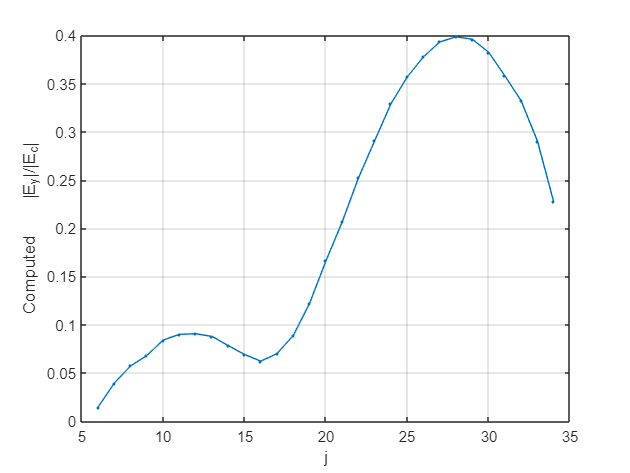


figure(3);
plot(6:34,EY1(6:34),'.-')
ylabel('Computed    |E_y|/|E_i_n_c|')
xlabel('j')
grid on

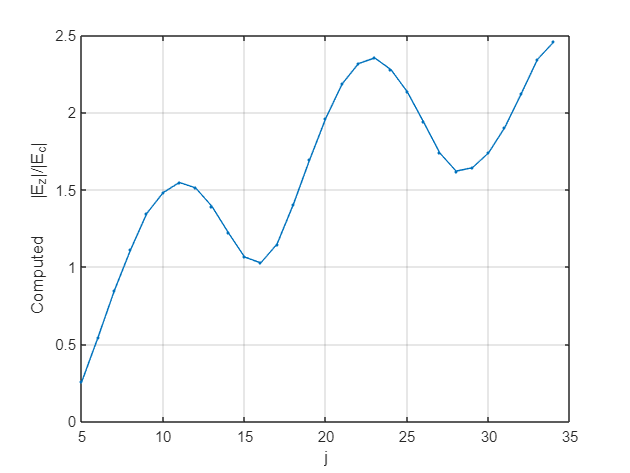


figure(4);
plot(5:34,EZ1(5:34),'.-')
ylabel('Computed    |E_z|/|E_i_n_c|')
xlabel('j')
grid on

We can see that the result is the same as the book claims to be!